syms t w;
f(t,w) = 1 + w/t;
y(t) = t*log(t) + 2*t;

for h=[1/10, 1/20, 1/40]
    [~, y_values] = Exact_Values(h, y);
    [t_values, w_values] = RK4(h, f);
    [error_values, max_error] = Error(y_values, w_values);
    fprintf('----------------------------------------------------\n');
    fprintf('RK4 method with h=1/%d:\n', 1/h);
    fprintf('Approximated values are:\n');
    disp(w_values)
    fprintf('Absolute errors for each values are\n');
    disp(error_values);
    fprintf('Maximum absolute error is: %e\n', max_error)
end

----------------------------------------------------


RK4 method with h=1/10:


Approximated values are:


    2.0000    2.3048    2.6188    2.9411    3.2711    3.6082    3.9520    4.3021    4.6580    5.0195    5.3863



Absolute errors for each values are


   1.0e-05 *

         0    0.0272    0.0485    0.0661    0.0811    0.0944    0.1064    0.1175    0.1280    0.1379    0.1475



Maximum absolute error is: 1.474767e-06


----------------------------------------------------


RK4 method with h=1/20:


Approximated values are:


    2.0000    2.1512    2.3048    2.4607    2.6188    2.7789    2.9411    3.1051    3.2711    3.4388    3.6082    3.7793    3.9520    4.1263    4.3021    4.4793    4.6580    4.8381    5.0195    5.2023    5.3863



Absolute errors for each values are


   1.0e-07 *

         0    0.0938    0.1759    0.2486    0.3138    0.3729    0.4270    0.4771    0.5238    0.5677    0.6092    0.6487    0.6864    0.7228    0.7579    0.7919    0.8250    0.8572    0.8888    0.9198    0.9502



Maximum absolute error is: 9.501746e-08


----------------------------------------------------


RK4 method with h=1/40:


Approximated values are:


    2.0000    2.0753    2.1512    2.2277    2.3048    2.3825    2.4607    2.5395    2.6188    2.6986    2.7789    2.8598    2.9411    3.0229    3.1051    3.1879    3.2711    3.3547    3.4388    3.5233    3.6082    3.6935    3.7793    3.8655    3.9520    4.0390    4.1263    4.2140    4.3021    4.3905    4.4793    4.5685    4.6580    4.7479    4.8381    4.9286    5.0195    5.1107    5.2023    5.2941    5.3863



Absolute errors for each values are


   1.0e-08 *

         0    0.0309    0.0596    0.0865    0.1118    0.1355    0.1579    0.1791    0.1992    0.2184    0.2367    0.2542    0.2710    0.2872    0.3028    0.3178    0.3323    0.3464    0.3601    0.3734    0.3864    0.3990    0.4114    0.4235    0.4353    0.4469    0.4583    0.4695    0.4805    0.4914    0.5021    0.5126    0.5230    0.5333    0.5435    0.5535    0.5634    0.5733    0.5830    0.5927    0.6023



Maximum absolute error is: 6.022818e-09


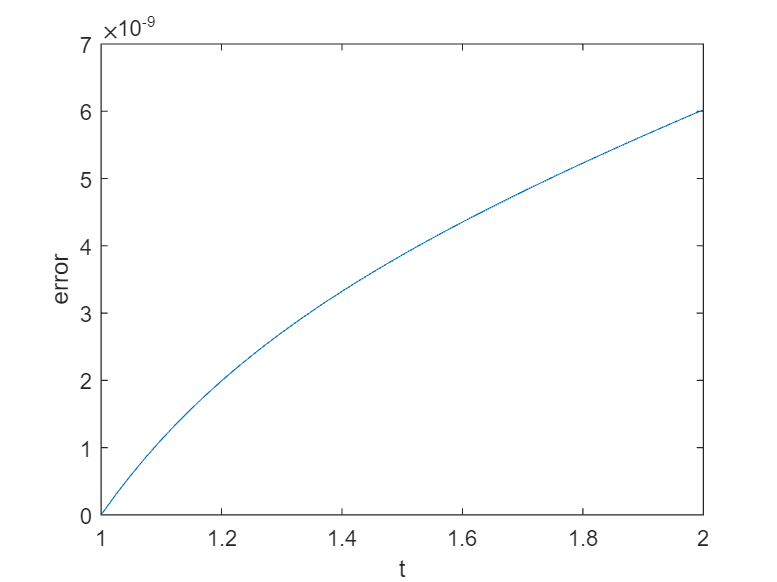


% last t_values and error_values are saved
% they are values associated with h=1/40
plot(t_values, error_values)
xlabel('t');
ylabel('error');

function [t_values, w_values] = RK4(h, f)
    % for speed, i did preallocation
    numbs = 1/h + 1;
    t_values = 1:h:2;
    w_values = zeros(1, numbs);

    t = 1;
    w = 2;
    w_values(1) = w;
    for i=2:numbs
        K1 = h * f(t,w);
        K2 = h * f(t+h/2, w+K1/2);
        K3 = h * f(t+h/2, w+K2/2);
        K4 = h * f(t+h, w+K3);
        w = w + (K1+2*K2+2*K3+K4)/6;
        t = t + h;

        w_values(i) = w;
    end
end

function [t_values, y_values] = Exact_Values(h, y)
    % for speed, i did preallocation
    numbs = 1/h + 1;
    t_values = 1:h:2;
    y_values = zeros(1, numbs);

    t = 1;
    for i=1:numbs
        y_values(i) = y(t);
        t = t + h;
    end
end

function [error_values, max_error] = Error(exact_values, approx_values)
    error_values = abs(exact_values - approx_values);
    max_error = max(error_values);
end